Polinomial Interpolation using SDP and LP for norm2 and maxnorm correspondedtly

clear all
close all
% Data points
n = 4; % n coefficients, n -1 order polynomial
h = 0.2 % step

h = 0.0500

%X = [0; 1; 2; 3;];
%Y = [1; 2; 1; 2];
X = 0 : h : 3;
%Y = zeros(length(X), 1);

%for i = 1 : length(X)
%   if  X(i) <= 1
%        Y(i) = 1 + h*(i-1);
%    elseif X(i) <= 2 
%        Y(i) = 3 - h*(i-1);
%    elseif X(i) <= 3
%        Y(i) = h*(i-1) -1;
%    end
%end

Y = [arrayfun(@(x) 1 + x, X(X <= 1)), ...
     arrayfun(@(x) 3 - x, X(X > 1 & X <= 2)), ...
     arrayfun(@(x) x - 1, X(X > 2 & X <= 3))]';

SDP solution to norm2


% variables to optimize
t = sdpvar(1);
a = sdpvar(1, n);
% objective function
F = t;
% constructing LMI
S = [];
for i = 1 : length(X)
S = [S; a*getPowers(X(i)) - Y(i)]; % preallocate for speed
end
LMI = [eye(length(X)) S;
      S'  t ];

constr = LMI >=0; % constraints for optimization 
opts = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 80);
optimize(constr, F, opts);


 num. of constraints =  5
 dim. of sdp    var  = 62,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.1e+01|4.6e+01|4.5e+05| 3.782000e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.999|1.4e-04|7.0e-02|4.5e+03| 3.709679e+03 -1.121788e+02| 0:0:00| chol  1  1 
 2|1.000|0.990|4.3e-07|4.7e-03|8.2e+01| 7.929417e+01 -2.107508e+00| 0:0:00| chol  1  1 
 3|0.988|0.988|2.5e-08|4.5e-04|9.5e-01| 2.974880e-02 -9.190169e-01| 0:0:00| chol  1  1 
 4|0.984|0.987|5.6e-09|4.6e-05|1.5e-02|-8.928533e-01 -9.075765e-01| 0:0:00| chol  1  1 
 5|0.968|0.983|1.8e-10|4.7e-06|5.0e-04|-9.071335e-01 -9.076083e-01| 0:

res = value(a);
fprintf("SDP solution: ")

SDP solution: 

disp(res)

    0.7907    2.6905   -2.2176    0.4928



LP with max norm

% objective function
F = [0; 0; 0; 0; 1];
% constraints
Y

Y =     1.0000
    1.0500
    1.1000
    1.1500
    1.2000
    1.2500
    1.3000
    1.3500
    1.4000
    1.4500


b = zeros(2*length(Y), 1)

b =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1 : length(Y)
    b(2*i-1) = Y(i);
    b(2*i) = -Y(i);
end
A1 = zeros(2*length(X), n + 1);
for i = 1 : length(X)
    A1(2*i -1,:) = [getPowers(X(i))', -1];
    A1(2*i,:) = [-getPowers(X(i))', -1];
end
res1 = linprog(F, A1, b);

Optimal solution found.



res1

res1 =     0.7990
    2.8642
   -2.3969
    0.5326
    0.2010


Plotting Poly

polySDP = wrev(res(1:4));
polyLP = wrev(res1(1:4));
x = linspace(-0.2, 3.2, 100);
y = polyval(polySDP, x);
figure
plot(x, y)
grid on
hold on
plot(X, Y)
hold on
y1 = polyval(polyLP, x)

y1 =     0.1260    0.2563    0.3803    0.4982    0.6101    0.7160    0.8162    0.9108    0.9999    1.0836    1.1621    1.2354    1.3038    1.3673    1.4261    1.4802    1.5300    1.5754    1.6165    1.6536    1.6868    1.7161    1.7418    1.7638    1.7825    1.7978    1.8100    1.8192    1.8254    1.8288    1.8296    1.8279    1.8238    1.8174    1.8088    1.7983    1.7859    1.7717    1.7559    1.7387    1.7200    1.7002    1.6792    1.6573    1.6345    1.6110    1.5870    1.5624    1.5376    1.5126


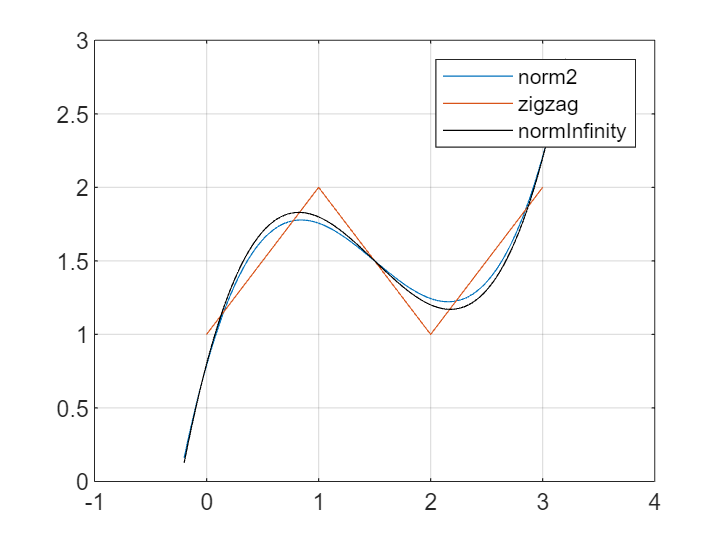

plot(x, y1, 'k')
legend("norm2", "zigzag", "normInfinity")

function vec = getPowers(x)
    vec = [1 ; x; x.^2; x.^3];
end